# ASTE 577 - Homework 3

## Problem 1

% Source for pressure and temperature data: https://hal.science/hal-03118616/document
rho0_titan = 28e-3*146.7e3/(8.314*93.7); %kg/m^3 
A_titan = 1.352*28e-3/(8.314*93.7); %1/m
%               m,      v,          g,      h,      rho0,       A,          M,      d_m,        d
properties = [
    ["GENESIS", 210,    11e3,       9.81,   85e3,   1.225,      1.38e-4,    28e-3,  364e-12,    1.51,   1.66e-5];
    ["STARDUST",45.8,   12.8e3,     9.81,   85e3,   1.225,      1.38e-4,    28e-3,  364e-12,    0.827,  1.66e-5];
    ["APOLLO",  5425,   -11.14e3,   9.81,   85e3,   1.225,      1.38e-4,    28e-3,  364e-12,    3.91,   1.66e-5];
    ["VIKING",  980,    4.61e3,     3.71,   80e3,   0.057,      1.28e-4,    44e-3,  330e-12,    3.54,   1.37e-5];
    ["MER B",   836,    5.55e3,     3.71,   80e3,   0.057,      1.28e-4,    44e-3,  330e-12,    2.65,   1.37e-5];
    ["PIONEER", 316.5,  11.54e3,    8.87,   70e3,   16.02,      1.61e-4,    44e-3,  330e-12,    1.42,   1.37e-5];
    ["HUYGENS", 318,    6e3,        1.352,  80e3,   rho0_titan, A_titan,    28e-3,  364e-12,    2.7,    1.66e-5]
    ];
for mission=transpose(properties)
    m = str2num(mission(2));
    v = str2num(mission(3));
    g = str2num(mission(4));
    h = str2num(mission(5));
    rho0 = str2num(mission(6));
    A = str2num(mission(7));
    M = str2num(mission(8));
    d_m = str2num(mission(9));
    d = str2num(mission(10));
    mu = str2num(mission(11));

    fprintf("%s \n", mission(1))
    E = m*(1/2*v^2 + g*h); %J
    fprintf("Entry Energy: %.4e [J]\n",E)
    rho = rho0 * exp(-A*h); %kg/m^3
    n = rho/M*6.022*10^23; %molecules/m^3
    lambda = 1/(n*pi*sqrt(2)*d_m^2); %m
    fprintf("Entry Mean Free Path: %.4e [m]\n", lambda)
    Re = rho*abs(v)*d/mu;%-
    fprintf("Entry Reynolds Number: %.4e [-]\n", Re)
    Kn = lambda/d; %-
    fprintf("Entry Knudsen Number: %.4e [-]\n", Kn)
    rho = rho0; %kg/m^3
    v = 2; %m/s
    n = rho/M*6.022*10^23; %molecules/m^3
    lambda = 1/(n*pi*sqrt(2)*d_m^2); %m
    fprintf("Surface Mean Free Path: %.4e [m]\n", lambda)
    Re = rho*abs(v)*d/mu;%-
    fprintf("Surface Reynolds Number: %.4e [-]\n", Re)
    Kn = lambda/d; %-
    fprintf("Surface Knudsen Number: %.4e [-]\n", Kn)
    fprintf(" \n")
end

GENESIS 


Entry Energy: 1.2880e+10 [J]


Entry Mean Free Path: 8.0110e-03 [m]


Entry Reynolds Number: 9.8656e+03 [-]


Entry Knudsen Number: 5.3053e-03 [-]


Surface Mean Free Path: 6.4478e-08 [m]


Surface Reynolds Number: 2.2286e+05 [-]


Surface Knudsen Number: 4.2701e-08 [-]


STARDUST 


Entry Energy: 3.7901e+09 [J]


Entry Mean Free Path: 8.0110e-03 [m]


Entry Reynolds Number: 6.2874e+03 [-]


Entry Knudsen Number: 9.6868e-03 [-]


Surface Mean Free Path: 6.4478e-08 [m]


Surface Reynolds Number: 1.2206e+05 [-]


Surface Knudsen Number: 7.7967e-08 [-]


APOLLO 


Entry Energy: 3.4114e+11 [J]


Entry Mean Free Path: 8.0110e-03 [m]


Entry Reynolds Number: 2.5871e+04 [-]


Entry Knudsen Number: 2.0489e-03 [-]


Surface Mean Free Path: 6.4478e-08 [m]


Surface Reynolds Number: 5.7708e+05 [-]


Surface Knudsen Number: 1.6491e-08 [-]


VIKING 


Entry Energy: 1.0704e+10 [J]


Entry Mean Free Path: 7.4186e-02 [m]


Entry Reynolds Number: 2.4248e+03 [-]


Entry Knudsen Number: 2.0956e-02 [-]


Surface Mean Free Path: 2.6494e-06 [m]


Surface Reynolds Number: 2.9457e+04 [-]


Surface Knudsen Number: 7.4841e-07 [-]


MER B 


Entry Energy: 1.3124e+10 [J]


Entry Mean Free Path: 7.4186e-02 [m]


Entry Reynolds Number: 2.1853e+03 [-]


Entry Knudsen Number: 2.7995e-02 [-]


Surface Mean Free Path: 2.6494e-06 [m]


Surface Reynolds Number: 2.2051e+04 [-]


Surface Knudsen Number: 9.9977e-07 [-]


PIONEER 


Entry Energy: 2.1271e+10 [J]


Entry Mean Free Path: 7.3936e-04 [m]


Entry Reynolds Number: 2.4431e+05 [-]


Entry Knudsen Number: 5.2068e-04 [-]


Surface Mean Free Path: 9.4266e-09 [m]


Surface Reynolds Number: 3.3209e+06 [-]


Surface Knudsen Number: 6.6385e-09 [-]


HUYGENS 


Entry Energy: 5.7584e+09 [J]


Entry Mean Free Path: 7.3086e-07 [m]


Entry Reynolds Number: 1.0547e+08 [-]


Entry Knudsen Number: 2.7069e-07 [-]


Surface Mean Free Path: 1.4980e-08 [m]


Surface Reynolds Number: 1.7152e+06 [-]


Surface Knudsen Number: 5.5481e-09 [-]


## Problem 2

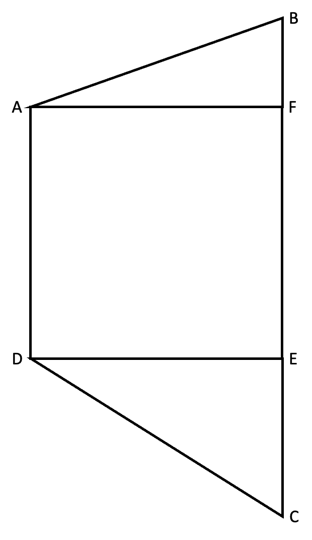

Triangle ABF:


$$c_{p,1} = c_{p,max}\sin^2\theta$$



$$\cos\theta = \frac{\overline{AF}}{\overline{AB}} \Rightarrow \theta = \cos^{-1}\frac{\overline{AF}}{\overline{AB}}$$



$$\Rightarrow c_{p,1} = c_{p,max}\sin^2\left[\cos^{-1}\frac{\overline{AF}}{\overline{AB}}\right]$$


Square AFED:


$$\Rightarrow c_{p,2} = c_{p,max}$$


Triangle DEC:


$$c_{p,3} = c_{p,max}\sin^2\theta$$



$$\cos\theta=\frac{\overline{DE}}{\overline{DC}} \Rightarrow \theta=\cos^{-1}\frac{\overline{DE}}{\overline{DC}}$$



$$\Rightarrow c_{p,3}=c_{p,max}\sin^2\left[\cos^-1\frac{\overline{DE}}{\overline{DC}}\right]$$


Total $c_p$:


$$c_p = c_{p,max}\frac{\overline{AB}\sin^2\left[\cos^{-1}\frac{\overline{AF}}{\overline{AB}}\right] + \overline{AD} + \overline{DC}\sin^2\left[\cos^{-1}\frac{\overline{DE}}\overline{DC}\right]}{\overline{AB}+\overline{AD}+\overline{DC}}$$



$$\Rightarrow c_p = 2\frac{\left(P_{shock}-P_e\right)\left(\overline{AB}\sin^2\left[\cos^{-1}\frac{\overline{AF}}{\overline{AB}}\right] + \overline{AD} + \overline{DC}\sin^2\left[\cos^{-1}\frac{\overline{DE}}\overline{DC}\right]\right)}{\rho_eV^2_e(\overline{AB}+\overline{AD}+\overline{DC})}$$
